# 功能：函数方程可视化

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

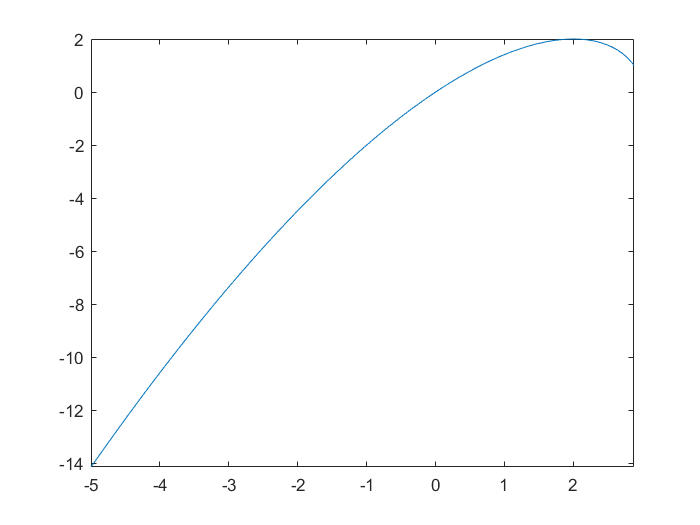

clear;clc;close all;
% 一元方程  y = x*sqrt(3-x);
f = @(x) x.*sqrt(3 - x);
figure
fplot(f);

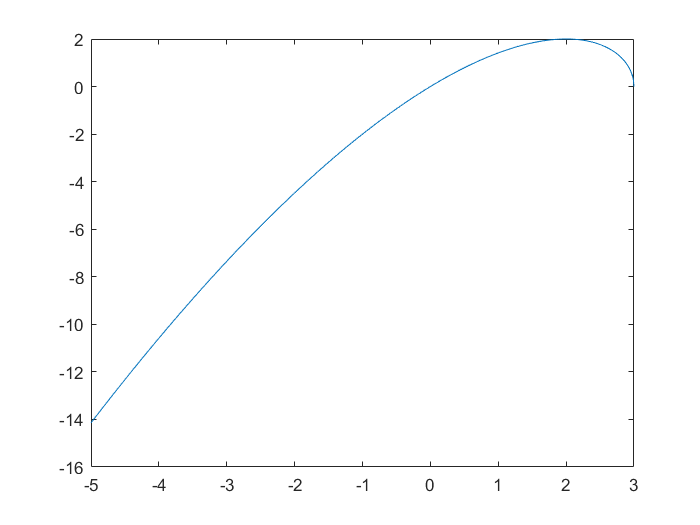

% 一般做法
x = -5:0.01:3;
y = x.*sqrt(3-x);
plot(x, y);

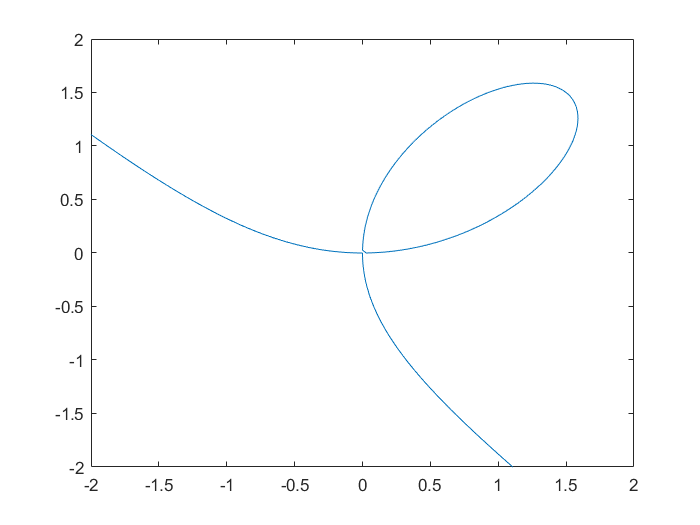


% 二元方程  x^3 + y^3 = 3*x*y
f = @(x, y) x.^3 + y.^3 - 3*x.*y;
figure
fimplicit(f, [-2, 2]);

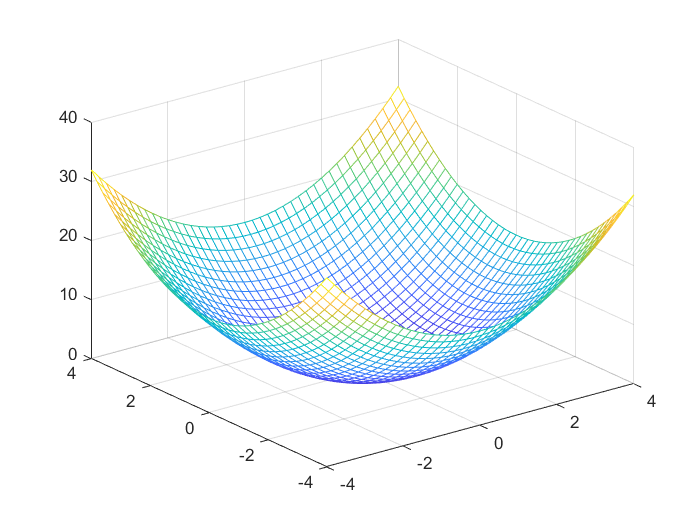

% 三元方程 z = x^2 + y^2
% 一般做法
[x, y] = meshgrid(-4:0.2:4);
z = x.^2 + y.^2;
figure
mesh(x, y, z);

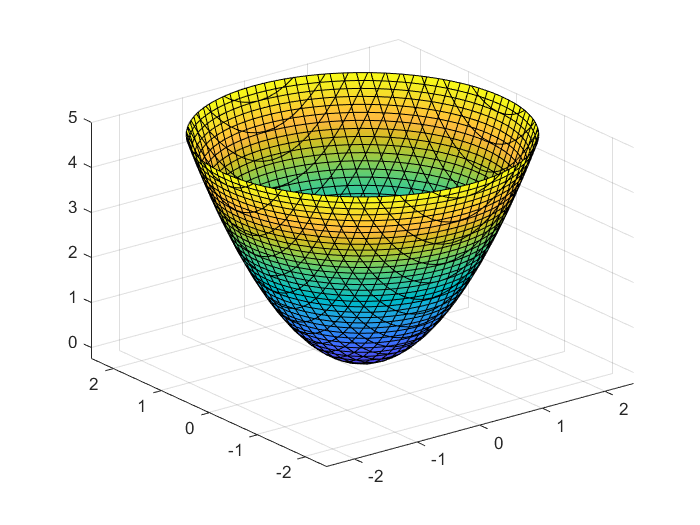


f = @(x,y,z) x.^2 + y.^2 - z;
figure
fimplicit3(f);

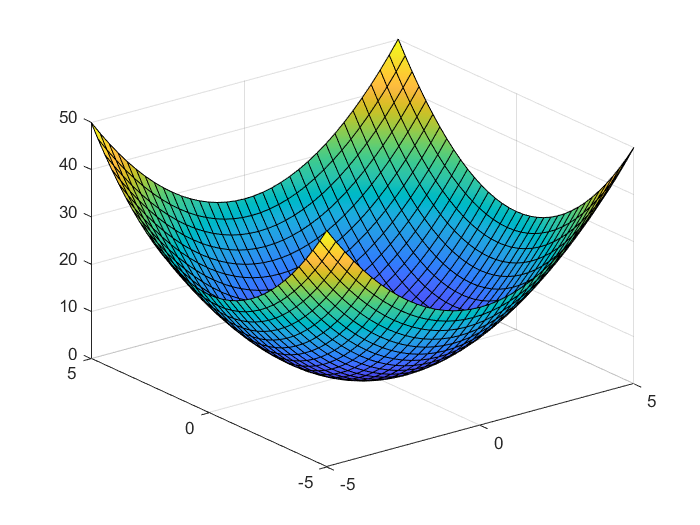

figure
fsurf(@(x, y) x.^2 + y.^2);

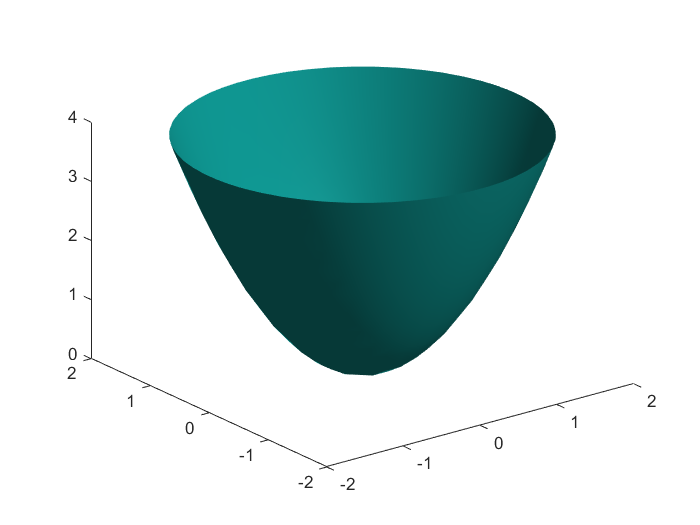

[x, y, z] = meshgrid(linspace(-4, 4, 40));
figure
isosurface(x, y, z, f(x, y, z),0);